## NASA Turbofan Level B2: **Modelling**

clc; close all; clear all; 
rng(42);

## Parameters

window_size = 5;
latent_k = 9;
fold_CV = 1;

stride = 1;

targetSensor = 'Sensor21';

%model = utils.PCR();
model = utils.PLS();

### Data loading and standardization

%% Load data
rawDataTable = load("NASA-Turbofan-data\sensorsDataTrain3.mat").raw_train_data;
rawDataTable(:, {'Cycle','OpSet1','OpSet2','OpSet3'}) = [];

%rawDataTable(:, {'Sensor9', 'Sensor14'}) = [];
%rawDataTable(:, {'Sensor7', 'Sensor8', 'Sensor9', 'Sensor12', 'Sensor13', 'Sensor14', 'Sensor20', 'Sensor21'}) = [];
%rawDataTable(:, {'Sensor2', 'Sensor4', 'Sensor7', 'Sensor8', 'Sensor9', 'Sensor12', 'Sensor13', 'Sensor14', 'Sensor15', 'Sensor20', 'Sensor21'}) = [];

%rawDataTable = rawDataTable(:, {'Sensor7', 'Sensor20', 'Unit', 'Sensor21'});

%% Remove constant Sensor columns
sensorIdxs = contains(rawDataTable.Properties.VariableNames, 'Sensor');
nonConstIdxs = mad(rawDataTable{:,:},1,1) > 1e-10;
keepSensorIdxs = sensorIdxs & nonConstIdxs;
colsToKeep = ~sensorIdxs | keepSensorIdxs;
dataTable = rawDataTable(:, colsToKeep);

### Manage Units (stored as tables)

units = unique(dataTable.Unit);
curves = cell(length(units), 1);
for i = 1:length(units)
    curves{i} = dataTable(dataTable.Unit == units(i), 2:size(dataTable, 2));
end

curves_shuffled = curves(randperm(length(curves)));

training_calibration_set = curves_shuffled(1:60);
validation_set = curves_shuffled(61:80);
testing_set = curves_shuffled(81:100);

### Allocate datasets

[training_calibration_X, training_calibration_Y, zscore_params] = utils.split_tables_into_windows_Xy(training_calibration_set, window_size, stride, targetSensor);
[validation_X, validation_Y, ~] = utils.split_tables_into_windows_Xy(validation_set, window_size, stride, targetSensor, zscore_params);
[testing_X, testing_Y, ~] = utils.split_tables_into_windows_Xy(testing_set, window_size, stride, targetSensor, zscore_params);

training_calibration_X = reshape(training_calibration_X, size(training_calibration_X, 1), []);
validation_X = reshape(validation_X, size(validation_X, 1), []);
testing_X = reshape(testing_X, size(testing_X, 1), []);

[training_X, training_Y, calibration_X, calibration_Y] = utils.splitThreeFoldCV(training_calibration_X, training_calibration_Y, fold_CV);

### Regression: fit and evaluate

model = model.fit(training_X, training_Y, latent_k);
training_Y_hat = model.predict(training_X);
calibration_Y_hat = model.predict(calibration_X);
validation_Y_hat = model.predict(validation_X);
testing_Y_hat = model.predict(testing_X);

### Regression: quality of performance

metrics = utils.RegressionMetrics(training_Y, training_Y_hat);
metrics.summary('Training');

--- Training Regression Metrics ---
RMSE:	0.06058
R2:	0.8216



metrics = utils.RegressionMetrics(calibration_Y, calibration_Y_hat, training_Y);
metrics.summary('Calibration');

--- Calibration Regression Metrics ---
RMSE:	0.06128
Q2:	0.8366



metrics = utils.RegressionMetrics(validation_Y, validation_Y_hat, training_Y);
metrics.summary('Validation');

--- Validation Regression Metrics ---
RMSE:	0.06116
Q2:	0.8366



metrics = utils.RegressionMetrics(testing_Y, testing_Y_hat, training_Y);
metrics.summary('Testing');

--- Testing Regression Metrics ---
RMSE:	0.06073
Q2:	0.8336


### Regression: prediction visualisation

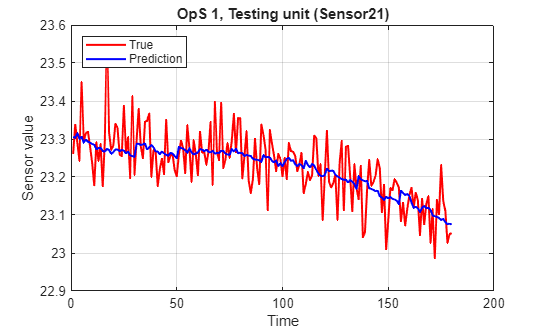

[testing_X_unit, testing_Y_unit, ~] = utils.split_tables_into_windows_Xy(testing_set(12), window_size, window_size, targetSensor, zscore_params);
testing_X_unit = reshape(testing_X_unit, size(testing_X_unit, 1), []);
testing_Y_hat_unit = model.predict(testing_X_unit);

utils.plot_curve_reconstruction(testing_Y_unit, testing_Y_hat_unit, sprintf('OpS 1, Testing unit (%s)', targetSensor))

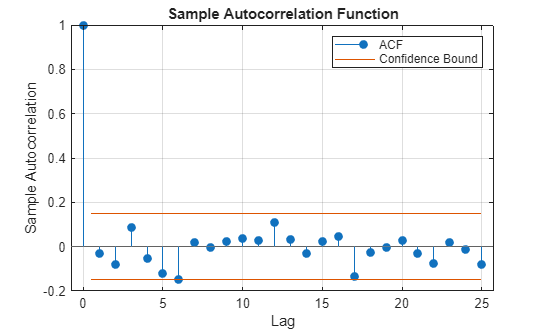

figure;
autocorr(reshape(testing_Y_unit', 1, []) - reshape(testing_Y_hat_unit', 1, []), "NumLags", 25)

### Regression: prediction autocorrelation

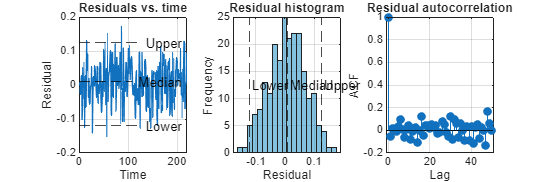

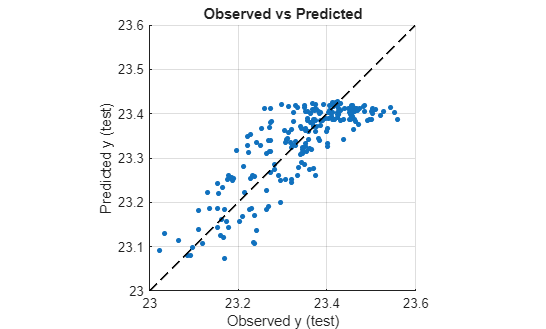

% Residual autocorrelation analysis across testing curves
num_curves = numel(testing_set);
all_acf = [];
all_y_sets = struct('y_true', {}, 'y_pred', {});

for i = 1:num_curves
    % Split one curve into consecutive windows
    [X, Y_true, ~] = utils.split_tables_into_windows_Xy(testing_set(i), window_size, window_size, targetSensor, zscore_params);
    X = reshape(X, size(X,1), []);       % flatten input windows
    Y_pred = model.predict(X);           % model predictions

    % Reconstruct true and predicted full curves
    c_true = reshape(Y_true', 1, []);
    c_pred = reshape(Y_pred', 1, []);
    all_y_sets(i).y_true = c_true;
    all_y_sets(i).y_pred = c_pred;

    % Residuals and autocorrelation
    res = c_true - c_pred;
    [acf, lags] = autocorr(res, 'NumLags', 50);   % compute autocorrelation up to 50 lags
    all_acf(i,:) = acf(:)';
end

% Example residual analysis plot
utils.resAnalysis(all_y_sets(1).y_true, all_y_sets(1).y_pred);

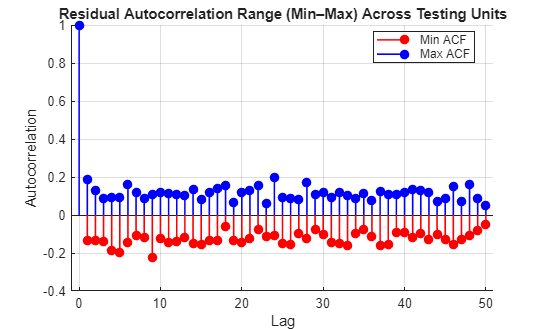


% Compute min and max autocorrelation for each lag
min_acf = min(all_acf, [], 1);
max_acf = max(all_acf, [], 1);
lags = lags(:);

% Stem plot of min–max range
figure;
hold on;
stem(lags, min_acf, 'r', 'filled', 'LineWidth', 1.2);  % min values
stem(lags, max_acf, 'b', 'filled', 'LineWidth', 1.2);  % max values

xlabel('Lag'); ylabel('Autocorrelation');
title('Residual Autocorrelation Range (Min–Max) Across Testing Units');
legend('Min ACF', 'Max ACF', 'Location','best');
grid on;